# Neural-Network 4

Created time : 2024/5/31 09:30

學號 : 109321019    姓名 : 涂价弘

clear
clc

## Exercise-1

## 导入预训练好的AlexNet,并确定该网络输入图像的大小以及分类种类的名称

net = alexnet;                                   % 将Alexnet导入工作区
% analyzeNetwork(net)
inputSize = net.Layers(1).InputSize;             % 获取Alexnet输入层中输入图像的大小
classNames = net.Layers(end).ClassNames;         % 获取Alexnet输出层中的分类


## 读入两幅MATLAB自带的RGB图像，并将图像的大小变换成与Alexnet输入层中输入图像相同的大小

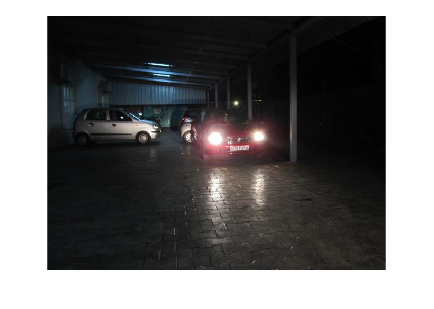

I = imread('car_2.jpg');
figure
imshow(I)

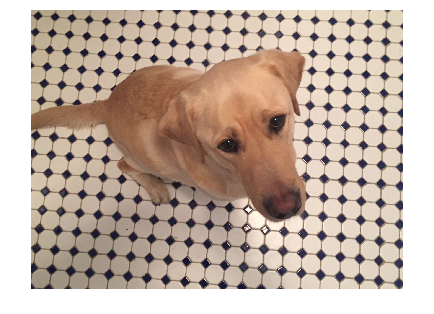

I = imresize(I,inputSize(1:2));

J= imread('kobi.png');
figure
imshow(J)

J = imresize(J,inputSize(1:2));

## 基于Alexnet对两幅输入的图像进行分类

[label1,scores1] = classify(net,I);
[label2,scores2] = classify(net,J);

## 在图像上显示分类结果及概率

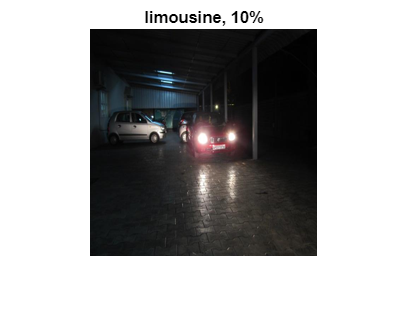

figure
imshow(I)
title(string(label1) + ", " + num2str(100*scores1(classNames == label1),3) + "%");

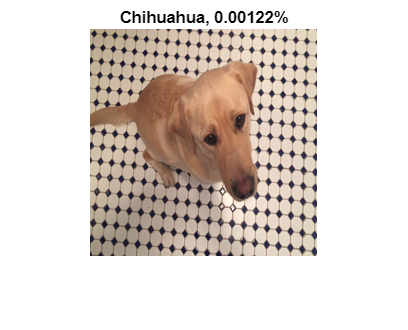


figure
imshow(J)
title(string(label2) + ", " + num2str(100*scores1(classNames == label2),3) + "%");

## Exercise-2

## 导入预训练好的GoogleNet,并确定该网络输入图像的大小以及分类种类的名称

net = googlenet;                                   % 将GoogleNet导入工作区
% analyzeNetwork(net)
inputSize = net.Layers(1).InputSize;             % 获取GoogleNet输入层中输入图像的大小
classNames = net.Layers(end).ClassNames;         % 获取GoogleNet输出层中的分类

## 读入两幅RGB图像，并将图像的大小变换成与GoogleNet输入层中输入图像相同的大小

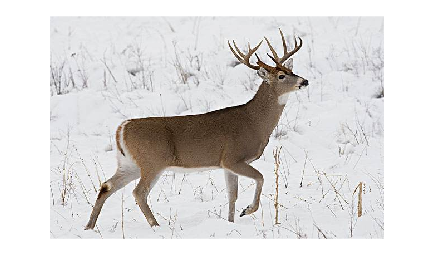

I = imread('./images/deer.jpg');
figure
imshow(I)

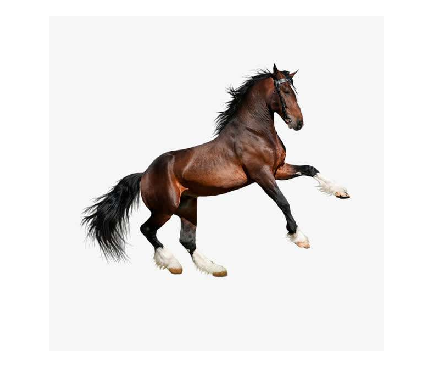

I = imresize(I,inputSize(1:2));

J= imread('./images/horse.jpg');
figure
imshow(J)

J = imresize(J,inputSize(1:2));

## 基于GoogleNet对两幅输入的图像进行分类

[label1,scores1] = classify(net,I);
[label2,scores2] = classify(net,J);

## 在图像上显示分类结果及概率

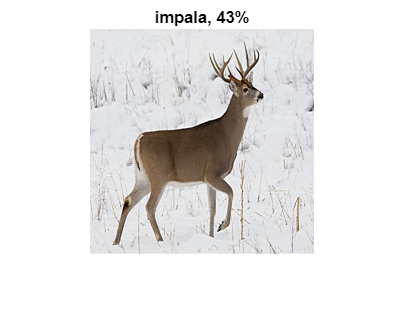

figure
imshow(I)
title(string(label1) + ", " + num2str(100*scores1(classNames == label1),3) + "%");

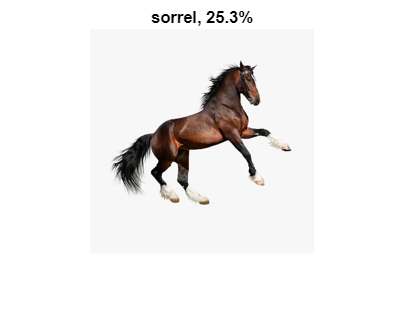


figure
imshow(J)
title(string(label2) + ", " + num2str(100*scores2(classNames == label2),3) + "%");

## Comparison

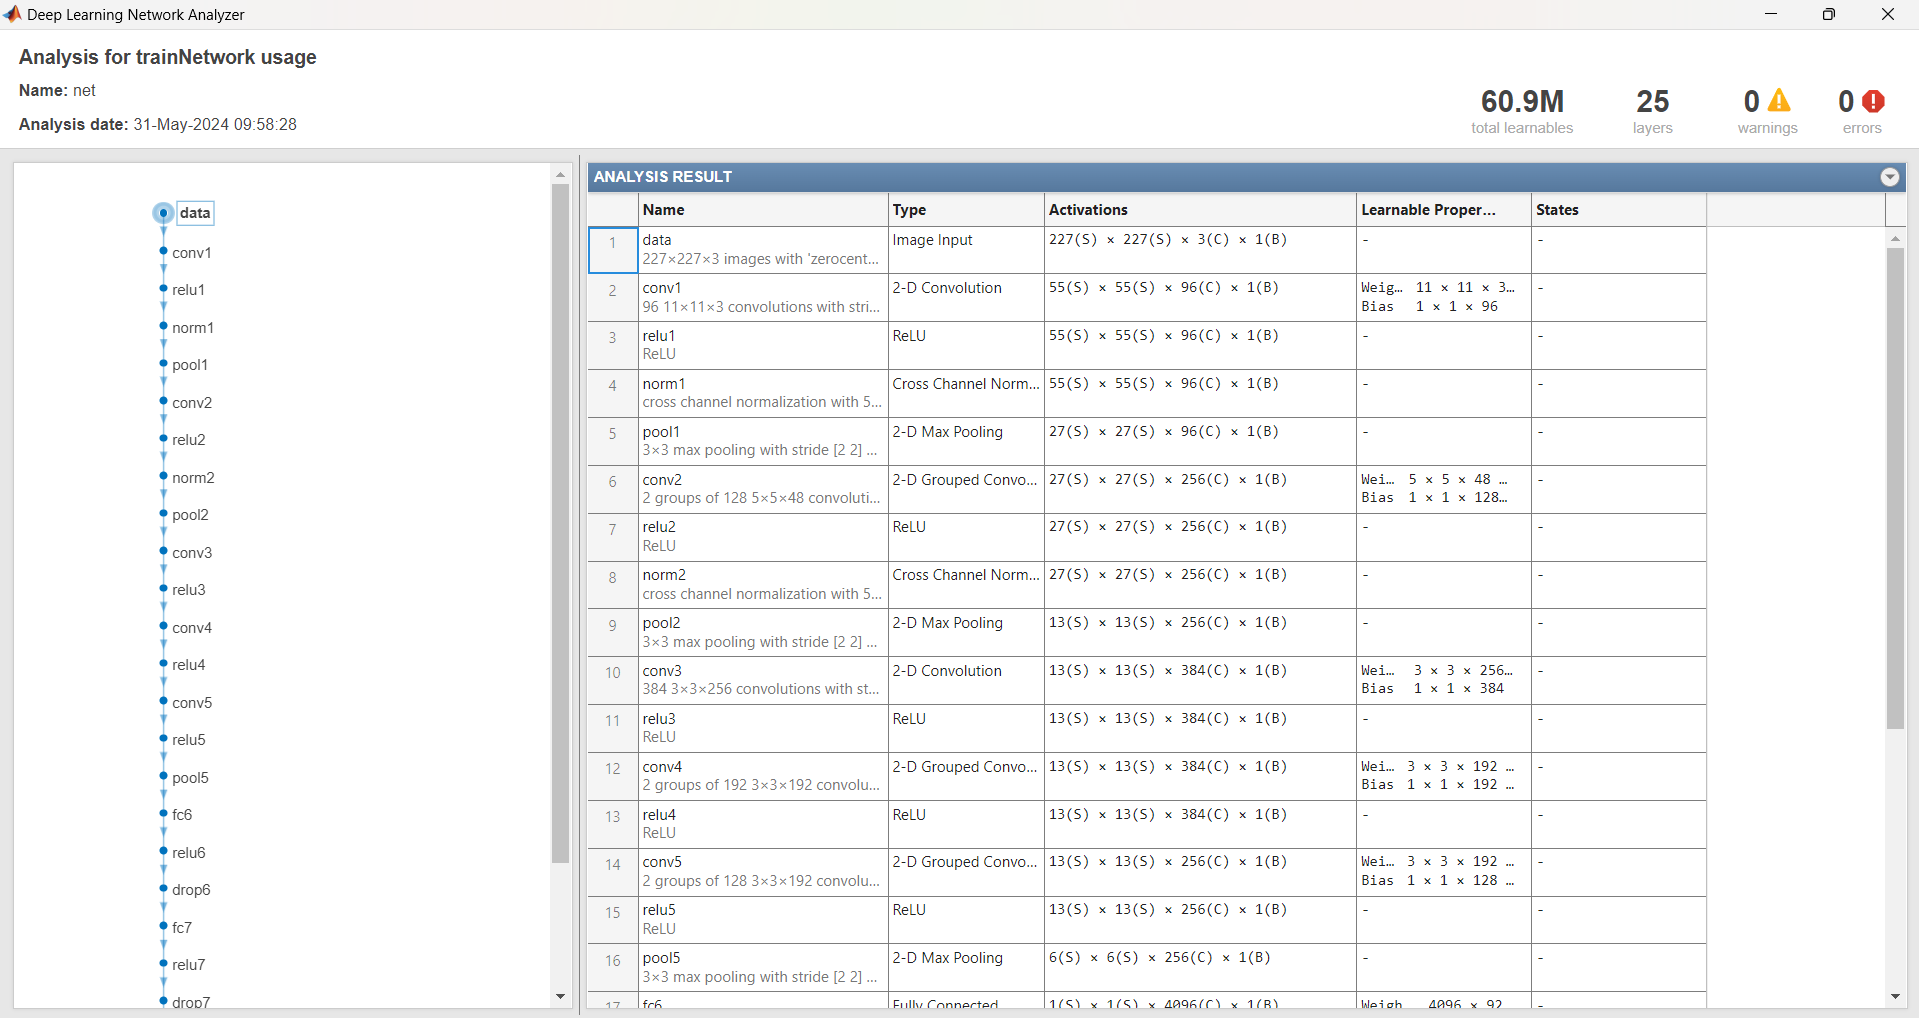

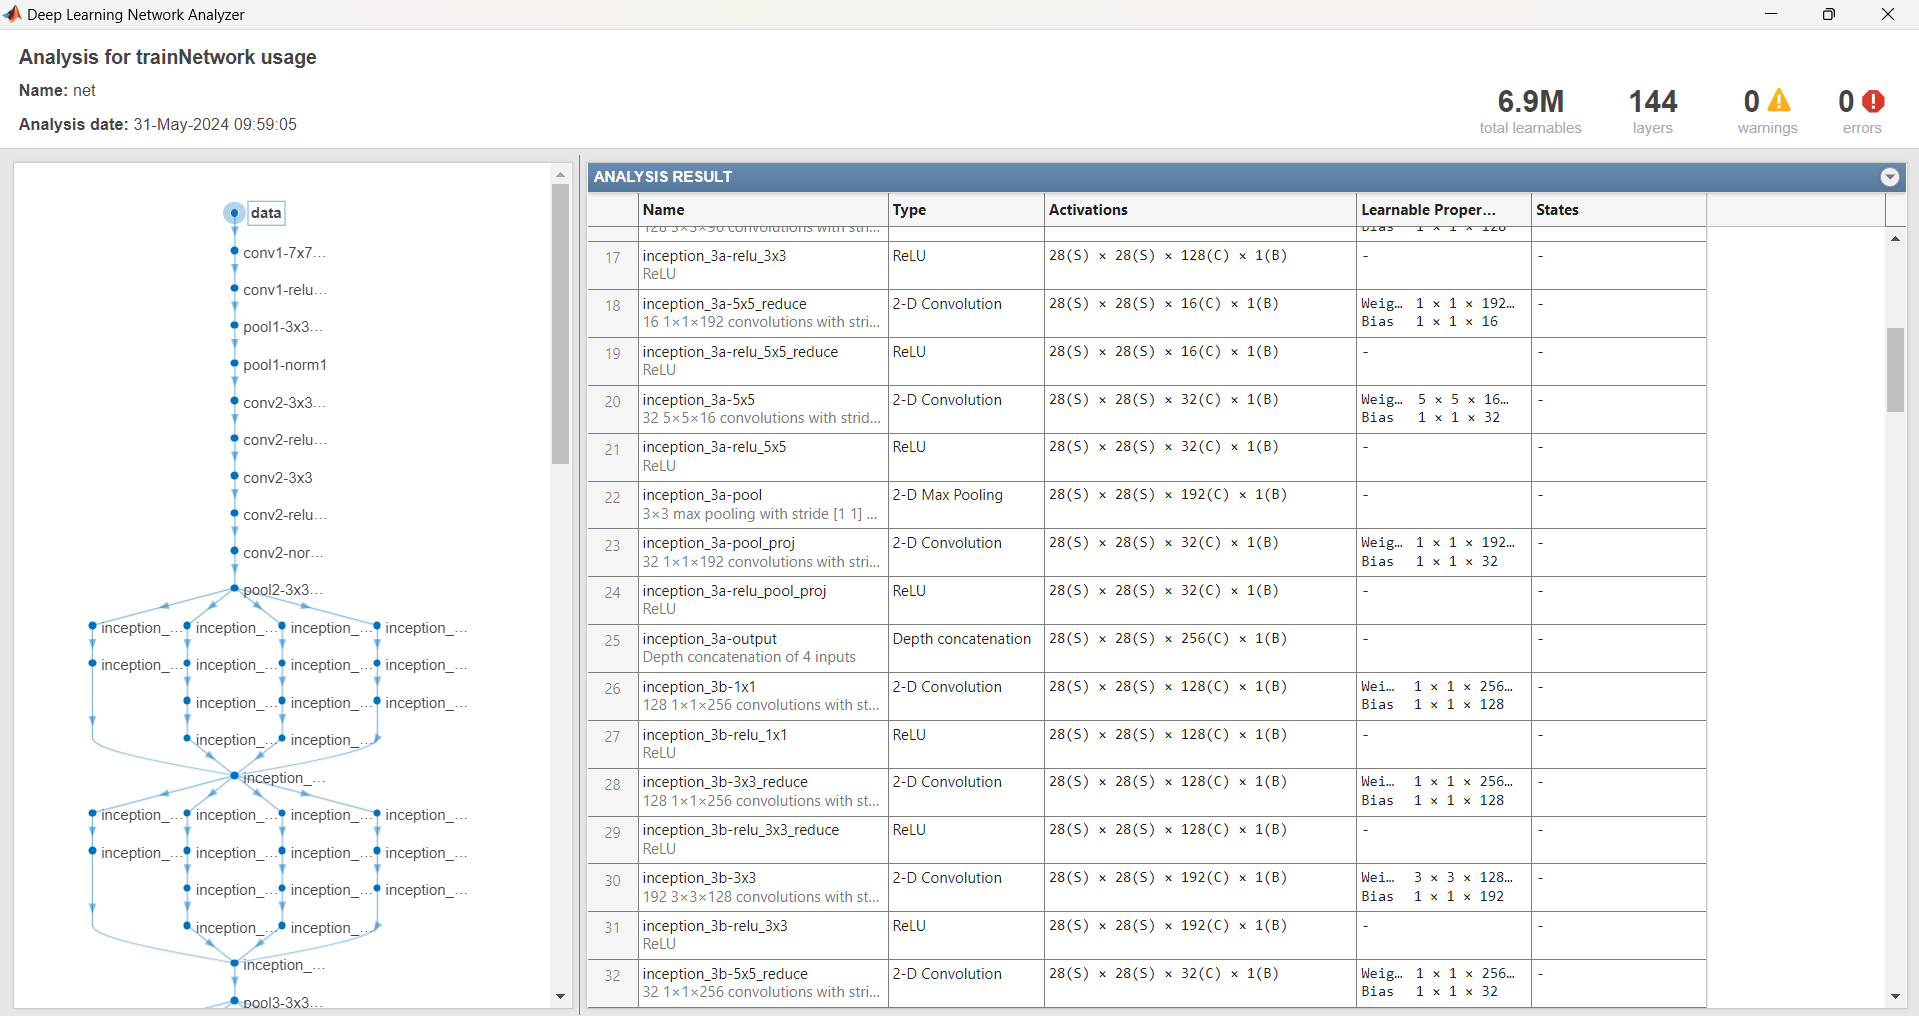

## Exercise-3

## 导入预训练好的AlexNet,并确定该网络输入图像的大小以及分类种类的名称

net = googlenet;                                   % 将Alexnet导入工作区
inputSize = net.Layers(1).InputSize;             % 获取Alexnet输入层中输入图像的大小
classNames = net.Layers(end).ClassNames;         % 获取Alexnet输出层中的分类

## 读入MATLAB自带的RGB图像，改变图像大小并添加噪声

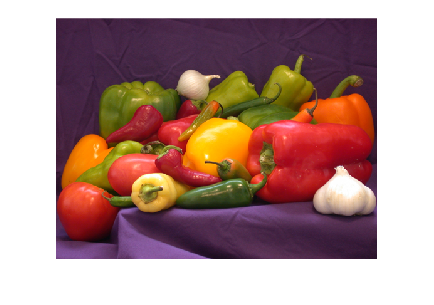

I = imread('peppers.png');
figure
imshow(I)

I = imresize(I,inputSize(1:2));
I1 = imnoise(I,'salt & pepper');   %添加椒盐噪声
I2 = imnoise(I, 'gaussian');

## 基于Alexnet对添加噪声后的图像进行分类

[label1,scores1] = classify(net,I1);
[label2,scores2] = classify(net,I2);

## 在图像上显示分类结果及概率

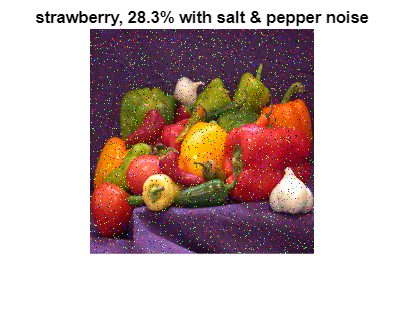

figure
imshow(I1)
title(string(label1) + ", " + num2str(100*scores1(classNames == label1),3) + "% with salt & pepper noise");

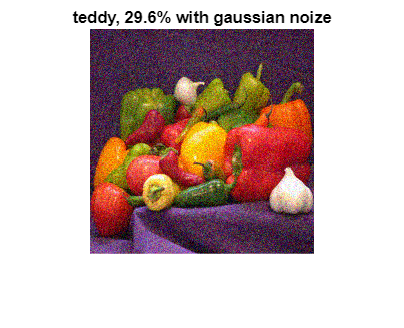


figure
imshow(I2)
title(string(label2) + ", " + num2str(100*scores2(classNames == label2),3) + "% with gaussian noize");

## Exercise-4

fprintf('Demo of how to run the code for:\n');

Demo of how to run the code for:


fprintf('Generate Slective Seach boxes used in RCNN and Fast RCNN\n');

Generate Slective Seach boxes used in RCNN and Fast RCNN


## Complie dependencies

cd SelectiveSearchCodeIJCV

% Compile anisotropic gaussian filter
if(~exist('anigauss'))
    fprintf('Compiling the anisotropic gauss filtering of:\n');
    fprintf('   J. Geusebroek, A. Smeulders, and J. van de Weijer\n');
    fprintf('   Fast anisotropic gauss filtering\n');
    fprintf('   IEEE Transactions on Image Processing, 2003\n');
    fprintf('Source code/Project page:\n');
    fprintf('   http://staff.science.uva.nl/~mark/downloads.html#anigauss\n\n');
    mex Dependencies/anigaussm/anigauss_mex.c Dependencies/anigaussm/anigauss.c -output anigauss
end

if(~exist('mexCountWordsIndex'))
    mex Dependencies/mexCountWordsIndex.cpp
end

% Compile the code of Felzenszwalb and Huttenlocher, IJCV 2004.
if(~exist('mexFelzenSegmentIndex'))
    fprintf('Compiling the segmentation algorithm of:\n');
    fprintf('   P. Felzenszwalb and D. Huttenlocher\n');
    fprintf('   Efficient Graph-Based Image Segmentation\n');
    fprintf('   International Journal of Computer Vision, 2004\n');
    fprintf('Source code/Project page:\n');
    fprintf('   http://www.cs.brown.edu/~pff/segment/\n');
    fprintf('Note: A small Matlab wrapper was made.\n');
    mex Dependencies/FelzenSegment/mexFelzenSegmentIndex.cpp -output mexFelzenSegmentIndex;
end

cd ..

## Generate Slective Seach boxes

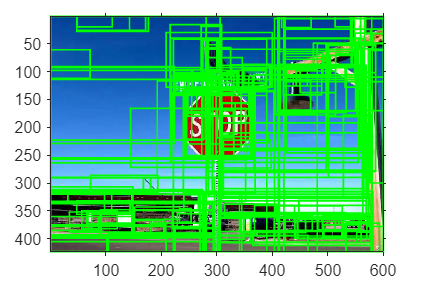

addpath('./src/select_search/')
addpath(genpath('./SelectiveSearchCodeIJCV'));

fast_mode = true;
img = imread('./images/stoptest.jpg');

ss_boxes = selective_search_boxes(img, fast_mode);

% Draw boxes
imshow(img);
axis on;
hold on;
for n = 1: 10:length(ss_boxes)
    box = ss_boxes(n, :);
    % box co-ordinates: [ymin, xmin, ymax, xmax], 1-based index
    xmin = box(2);
    ymin = box(1);
    w = box(4) - box(2);
    h = box(3) - box(1);
    rectangle('Position', [xmin,ymin,w,h], 'EdgeColor','g','LineWidth',1)
end

## Exercise-5

## 步骤1：构建一个卷积神经网络

输入层（与训练集图像的大小相同）

% inputLayer = imageInputLayer([32 32 3]);
% % 卷积层
% filterSize = [5 5]; %卷积核大小
% numFilters = 32; %卷积核个数
% middleLayers = [
%     convolution2dLayer(filterSize, numFilters, 'Padding', 2)
%     batchNormalizationLayer
%     reluLayer()
%     maxPooling2dLayer(3, 'Stride', 2)
%     convolution2dLayer(filterSize, numFilters, 'Padding', 2)
%     batchNormalizationLayer
%     reluLayer()
%     maxPooling2dLayer(3, 'Stride',2)
%     convolution2dLayer(filterSize, 2 * numFilters, 'Padding', 2)
%     batchNormalizationLayer
%     reluLayer()
%     maxPooling2dLayer(3, 'Stride',2)
%     ];
% % 全连接层
% finalLayers = [
%     fullyConnectedLayer(64)
%     batchNormalizationLayer
%     reluLayer
%     fullyConnectedLayer(10)
%     softmaxLayer
%     classificationLayer
%     ];
% % 构建整个卷积神经网络
% layers = [
%     inputLayer
%     middleLayers
%     finalLayers
%     ];

## 步骤2：采用CIFAR-10数据集，训练所构建的卷积神经网络；

导入CIFAR-10数据集，要求与步骤详见本书4.7节

% [trainingImages,trainingLabels,testImages,testLabels] = helperCIFAR10Data.load('cifar10Data');
% 
% % 显示其中的100幅
% figure
% thumbnails = trainingImages(:,:,:,1:100);
% montage(thumbnails)
% 
% % 设置训练策略参数
% opts = trainingOptions('sgdm', ...
%     'Momentum', 0.9, ...
%     'InitialLearnRate', 0.001, ...
%     'LearnRateSchedule', 'piecewise', ...
%     'LearnRateDropFactor', 0.1, ...
%     'LearnRateDropPeriod', 8, ...
%     'MaxEpochs', 25, ...
%     'MiniBatchSize', 128, ...
%     'Verbose', true);
% 
% % 训练网络，trainNetwork函数的参数依次分别为：训练数据集，训练集标签，网络结构，训练策略。
% cifar10Net = trainNetwork(trainingImages, trainingLabels, layers, opts);

## 步骤3：验证卷积神经网络的分类效果.

% YTest = classify(cifar10Net, testImages);
% % 计算正确率.
% accuracy = sum(YTest == testLabels)/numel(testLabels)

cifar10Net = load('./mat/cifar10Net.mat')

cifar10Net = struct with fields:
    cifar10Net: [1×1 SeriesNetwork]


## 步骤4：训练RCNN检测器

导入41张包括有“Stop sign”交通标志的图像

data = load('stopSignsAndCars.mat', 'stopSignsAndCars');
stopSignsAndCars = data.stopSignsAndCars;
% 设置图像路径参数
visiondata = fullfile(toolboxdir('vision'),'visiondata');
stopSignsAndCars.imageFilename = fullfile(visiondata, stopSignsAndCars.imageFilename);
% 显示数据
summary(stopSignsAndCars)

Variables:

    imageFilename: 41×1 cell array of character vectors

    stopSign: 41×1 cell

    carRear: 41×1 cell

    carFront: 41×1 cell



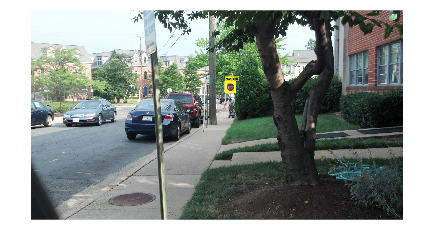

% 只保留文件名及其所包含的“stop sign”区域
stopSigns = stopSignsAndCars(:, {'imageFilename','stopSign'});
% 显示一张照片及其所包含的真实“stop sign”区域
I = imread(stopSigns.imageFilename{1});
I = insertObjectAnnotation(I,'Rectangle',stopSigns.stopSign{1},'stop sign','LineWidth',8);
figure
imshow(I)


% 设置训练策略
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 128, ...
    'InitialLearnRate', 1e-3, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.1, ...
    'LearnRateDropPeriod', 100, ...
    'MaxEpochs', 35, ...
    'Verbose', true);

% 训练R-CNN网络.
rcnn = trainRCNNObjectDetector(stopSigns, cifar10Net.cifar10Net, options, ...
    'NegativeOverlapRange', [0 0.3], 'PositiveOverlapRange',[0.5 1])

*******************************************************************
Training an R-CNN Object Detector for the following object classes:

* stopSign

--> Extracting region proposals from 41 training images...done.

--> Training a neural network to classify objects in training data...

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       29.69% |       0.7135 |          0.0010 |
|       6 |          50 |       00:00:31 |       98.44% |       0.0390 |          0.0010 |
|      12 |         100 |       00:01:02 |       99.22% |       0.0264 |          0.0010 |
|      17 |    

rcnn =   rcnnObjectDetector with properties:

               Network: [1×1 SeriesNetwork]
     RegionProposalFcn: @rcnnObjectDetector.proposeRegions
            ClassNames: {'stopSign'  'Background'}
    BoxRegressionLayer: 'conv_3'


## 步骤5：检验检测器的对“Stop sign”交通标志的图像的检测效果

检测“Stop sign“标志

% 载入测试图片
testImage = imread('./images/StopSign_1.jpg');

[bboxes,score,label] = detect(rcnn,testImage,'MiniBatchSize',128)

bboxes =     -3    89   154   141


score = single
0.9997

label = categorical
     stopSign 


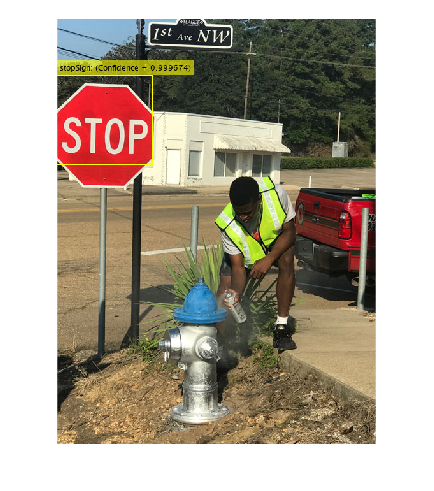

% 标注置信度
[score, idx] = max(score);
bbox = bboxes(idx, :);
annotation = sprintf('%s: (Confidence = %f)', label(idx), score);
outputImage = insertObjectAnnotation(testImage, 'rectangle', bbox, annotation);
figure
imshow(outputImage)